# Oscylator nieharmoniczny

## Wstęp

Rozpatrujemy ruch tylko wzdłuż osi x. Mamy punkt materialny o masie $m$ na który działa siła sprężysta $F_{\text s}\left(x\right)$ oraz siła wymuszająca $F_{\text{ext}}(t, x)$oraz siła tarcia $F_\text{dump}(t, x, v)$, gdzie $x$ jest położeniem (współrzędną środka masy), $v$ prędkością, $t$ czasem. Z definicji prędkość jest pochodą położenia po czasie, czyli wynikiem dzielenia zmiany wartości współrzędnej przez czas w jakim się ta zmiana realizuje. Formalnie przyrost czasu powinien być "nieskończenie mały". Analogicznie przyspieszenie jest pochodną prędkości po czasie, czyli ilorazem przyrostu prędkości przez czas (przyrost czasu) potrzebny do tej zmiany prędkości. Zaś z drugiej zasady dynamiki Newtona wynika że siła wypadkowa $F=F_{\text{s}}+F_{\text{ext}}+F_\text{dump}$ (czyli suma siły sprężystej, zewnętrznej siły wymuszającej i siły tarcia) nadaje punktowi materialnemu przyspieszenie $a = F / m$ (wzdłuż osi x, w innych kierunkach ruch jest z założenia niemożliwy). Możemy więc zapisać, dla małych $\Delta t \to 0$, dwa równania:


$$\frac {\Delta x }{\Delta t}=v$$



$$\frac {\Delta v}{\Delta t} = \frac F m$$


albo użyć zapisu w którym zamiast przyrostów skończonych wprost pojawiają się symbole pochodnych, jak poniżej:


$$\frac {\text{d} x }{\text{d} t}=v$$



$$\frac {\text{d} v}{\text{d} t} = \frac F m$$


Problem w tym, że nawet jeżeli potrafimy dość dobrze obliczyć siłę wypadkową $F$ (która ogólnie biorąc może zależeć od czasu, położenia, prędkości), to taki układ równań jak powyżej nieszczególnie może dać się rozwiązać - zwłaszcza jeżeli odejdziemy od "przetartych szlaków" i np. siła sprężysta nie będzie spełniać prawa Hook'a (czyli nie będzie wprost proporcjonalna do odkształcenia sprężyny), opór będzie zależał od zwrotu prędkości (inny dla ujemnych i inny dla dodatnich prędkości) itp. itd.

Dlatego, jeżeli nie możemy (lub nie chcemy) rozwiązywać takich układów równań analitycznie możemy użyć Matlaba do rozwiązania ich numerycznie.

## Obliczenia

### Skrypt

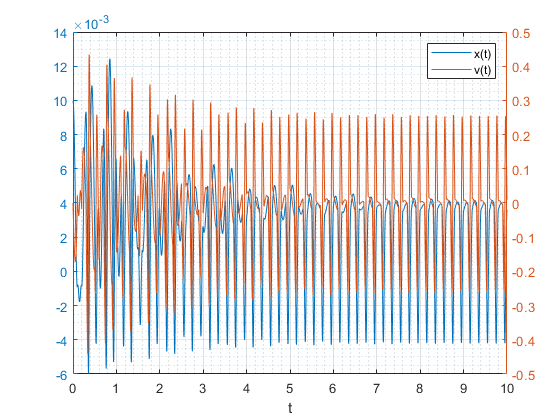

% Parametry modelu.
% Określenie które zmienne są (w tej części) skryptu zmiennymi globalnymi.

global Fs Fext Fdump
global m

m = 0.1; % masa wprawiana w drgania, w kilogramach

% Warunki początkowe

x0 = 0.01; % położenie początkowe w metrach
v0 = 0.0;  % prędkość początkowa w metrach na sekundę

initial_conditions = [x0, v0];

% Zakres zmiennej niezależnej

tstart = 0.0; % początek, w sekundach
tstop = 10.0; % koniec, w sekundach

% Ustalenie z jakich funkcji budujemy nasz model.

Fs = @Fs3;
Fext = @Fext3;
Fdump = @Fdump2;

% Ustalenie różnych opcji dla "rozwiązywacza ode".

opt = odeset('MaxStep', 0.001);

% Same obliczenia jako takie. Ponieważ wyniki są zapisywane do zmiennych t
% oraz q to samo wywołanie funkcji odexxx nic nie rysuje samo z siebie.

[t, q] = ode23tb(@equations, [tstart, tstop], initial_conditions, opt);

% Przepakowanie wyników do wygodniejszej postaci.

x = q(:,1);
v = q(:,2);

% Narysowanie wykresu zależności od czasu.

plotyy(t, x, t, v);
grid on;
grid minor;
xlabel('t');
legend('x(t)', 'v(t)');

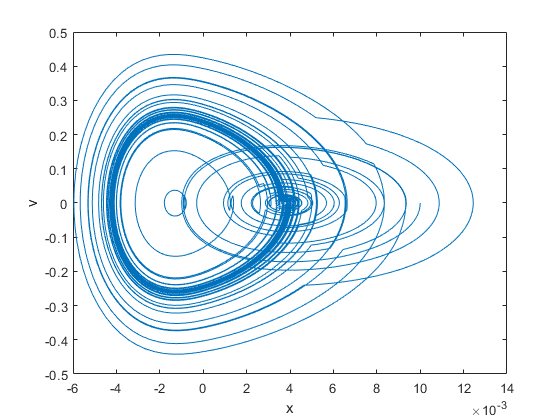

% Narysowanie diagramu fazowego

plot(x,v);
xlabel('x');
ylabel('v');

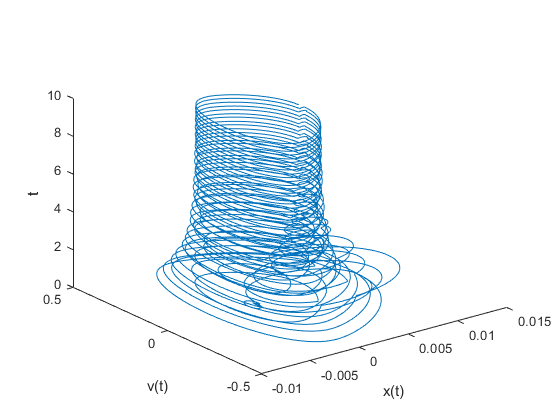

% Diagramu fazowy nieco inaczej (3D)

plot3(x,v,t);
xlabel('x(t)');
ylabel('v(t)');
zlabel('t');

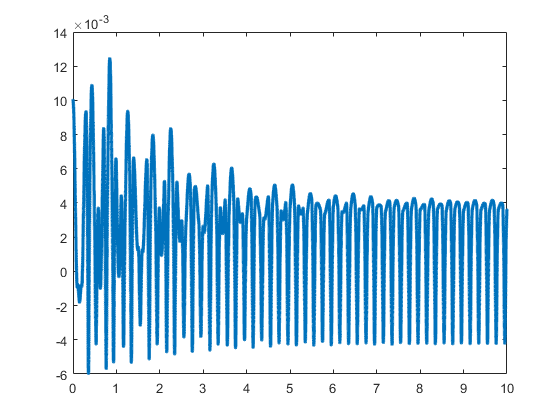

ti = linspace(t(1), t(end), 3 * length(t));
xi = interp1(t,x, ti, 'pchip');
plot(ti, xi, '.');

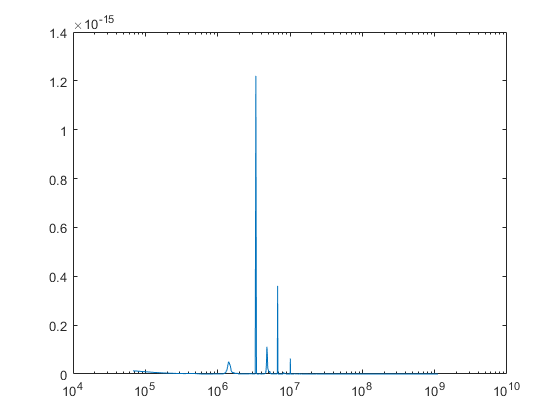

[psd, freq] = powerspectrum( xi, 1/(t(2) - t(1)) );
semilogx(freq, psd);

%xlim([0.01, 100000]);

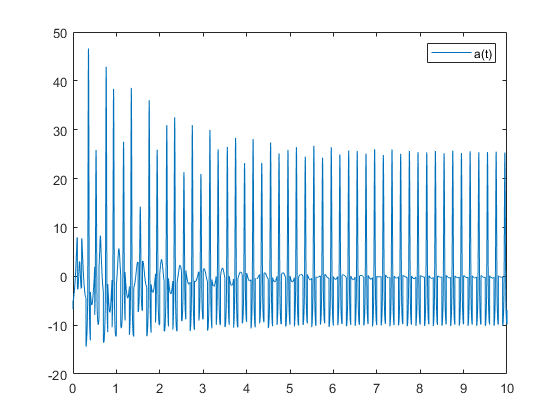

% Przedmiot: Techniki Obliczeniowe 
% Kierunek studiów: Mechatronika 
% Semestr: 2
% Rok akademicki: 2019/2020
% Data (dzień-miesiąc-rok): 18-06-2020
%
% Imię:             Mariusz
% Nazwisko:         Sendyk
% Numer albumu ZUT: 46767

% Obliczenie przyspieszenia z pochodnej

a = f_prim(t ,v);

% Rysowanie wykresu przypsieszenia
plot(t, a);
legend('a(t)');

% Obliczanie przyspieszenia z drugiej zasady dynamiki Newtona

F = Fs(x) + Fext(x,t) + Fdump(x,v,t); % Obliczenie siły

a2 = F/m;

% Rysowanie wykresu przyspieszenia

plot(t, a);
legend('a(t)');

**Funkcja do obliczania pochodnej centralnej**

function pochodna=f_prim(x,y)
 
N = length(y);
pochodna = zeros(1,N);
pochodna(1) = (y(2) - y(1)) / (x(2) - x(1));
 
for i = 2 : N-1
    pochodna(i) = (y(i+1) - y(i-1)) / (x(i+1) - x(i-1));
end
 
pochodna(N) = (y(N) - y(N-1)) / (x(N) - x(N-1));
 
end

### Funkcja obliczająca prawe strony równań

Funkcja obliczająca prawe strony równań ma dwa parametry t oraz q. W chwili wywołania pierwszy z nich zawiera wartość zmiennej niezależnej, czyli w naszym przypadku czasu (mierzonego w sekundach). Drugi to jednokolumnowa macierz ze zmiennymi zależnymi których przyrosty (czyli pochodne) są opisane równaniami. Czyli w naszym przypadku jest to wektor o jednej kolumnie i dwóch wierszach, zawierający położenie i prędkość punktu. Zauważmy że w równaniach nie ma ani przyrostu przyspieszenia $\Delta a$, ani pochodnej $\text{d}a / \text{d}t$, więc przyspieszenia nie ma w parametrze q.

function dqdt = equations(t, q)

    % Rozpakowanie wektora q na czytelniejsze w użyciu zmienne.
       
    x = q(1);  % położenie, w metrach
    v = q(2);  % prędkość, w metrach na sekundę

    % Masa punktu materialnego (wyrażona w kilogramach) jest zmienną
    % globalną aby można łatwo ją zmieniać gdyby okazało się to potrzebne.
    
    global m

    % Obliczanie siły wypadkowej wykonywane jest przez funkcje także
    % przekazywane jako zmienne globalne. Funkcje te powinny zwracać
    % wartości odpowiednich sił wyrażone w niutonach.
    
    global Fs Fext Fdump
    
    F = Fs(x) + Fext(x,t) + Fdump(x,v,t);
    
    % Druga zasada dynamiki Newtona dla ciała o stałej masie.
    
    a = F / m;
    
    % Zapisanie wartości pochodnych w odpowiednich zmiennych. Pochodna
    % dx/dt czyli przyrost prędkości w czasie to po prostu prędkość.
    % Pochodna dv/dt to po prostu przyspieszenie.
    
    dxdt = v;
    dvdt = a;
    
    % Funkcja taka jak equations, aby być przydatna w wywołaniu ode45 itp.
    % musi zwracać pochodne w postaci wektora kolumnowego. To musi być
    % wektor "pionowy", inaczej nie zadziała.
    
    dqdt = [dxdt; dvdt];
end


### Funkcje obliczające siły sprężyste

Zamiast jednej jest kilka funkcji - dzięki temu dość łatwo można modyfikować model jaki ma być rozwiązywany. Dla łatwiejszej orientacji nazywają się one Fs1, Fs2, ... ale w chwili gdy przeprowadzane są obliczenia musi być ustalone jaka konkretnie z nich ma być użyta jako globalnie dostępna Fs.

#### Siła sprężysta spełniająca prawo Hook'a

function F = Fs1(x)
    k = 100; % stała, wyrażona w N/m
    F = - k * x;
end

#### Symetryczna nieliniowa siła sprężysta

function F = Fs2(x)

    % Trik pozwalający zapisać dane w postaci ładnej tabelki już w kodzie
    % źródłowym. Oczywiście zawartość table może być też załadowana z
    % pliku, poleceniem load albo readmatrix.

    table = [ 
            0.00    0.00
            0.01    1.00
            0.02    1.90
            0.03    2.50
            0.05    3.00
        ];
    x_values = table(:,1);
    F_values = table(:,2);

    % Sprawdzamy w którą stronę nastąpiło wychylenie, odpowiednio do tego
    % będziemy ustalali znak siły. Używamy funkcji sign(x), która przyjmuje
    % wartości -1, 0, 1 odpowiednio do wartości (ujemnej, zero, dodatniej)
    % jaka jest w zmiennej x.
    
    F = -sign(x) * interp1(x_values, F_values, abs(x), 'pchip', 'extrap');
end

#### Niesymetryczna nieliniowa siła sprężysta

function F = Fs3(x)

    % Uwaga: znak wartości siły powinien być odpowiedni - czyli ujemny dla
    % dodatnich wychyleń.
   
    table = [ 
           -0.07  200.00 
           -0.02   20.00
           -0.01   10.00
            0.00    0.00
            0.01   -1.00
            0.02   -1.90
            0.03   -2.50
            0.05   -3.00
        ];
    x_values = table(:,1);
    F_values = table(:,2);

    % Obliczenia są nawet prostsze niż poprzednio (w Fs1).
    
    F = interp1(x_values, F_values, x, 'pchip', 'extrap');
end 

### Funkcje obliczające wymuszenie

#### Bez wymuszenia

function F = Fext1(x,t)

    F = 0;  % wynik jest zawsze zerowy, niezależnie od x i t.
    
end

#### Funkcja harmoniczna

function F = Fext2(x,t)

    amplitude = 0.5; % amplituda siły wymuszającej, w niutonach
    freq = 5;        % częstotliwość siły wymuszającej, w hercach

    F = amplitude * sin(2*pi*freq * t);    
end

#### Impulsy prostokątne

function F = Fext3(x,t)

    amplitude = 0.5; % amplituda siły wymuszającej, w niutonach
    freq = 5;        % częstotliwość siły wymuszającej, w hercach

    F = amplitude * sign(sin(2*pi*freq * t));    
end

### Funkcje obliczające siłę tarcia

#### Bez tarcia

function F = Fdump1(x,v,t)

    F = 0;  % wynik jest zawsze zerowy, niezależnie od x i t.
    
end

#### Tarcie proporcjonalne do prędkości

Tarcie proporcjonalne do prędkości jest typowe dla oporu powietrza (albo cieczy) przy niezbyt dużych prędkościach, czyli wtedy gdy przepływ jest laminarny, pozbawiony wirów.

function F = Fdump2(x,v,t)

    % Uwaga: siła powinna mieć znak przeciwny do kierunku ruchu.

    coefficient = 0.1; % współczynnik oporu wyrażony w niutonach na metr/sekundę.
    F = - coefficient * v;    
    
end